# RVC2: Chapter 2

clear all
close all
clc

## 2.1.1.1 2d rotation


R = rot2(0.2) % 弧度

R =     0.9801   -0.1987
    0.1987    0.9801



det(R)

ans = 1


det(R*R)

ans = 1


syms theta
R = rot2(theta)

$$R = \left(\begin{array}{cc} \cos\left(\theta \right) & -\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

simplify(R*R)

$$ans = \left(\begin{array}{cc} \cos\left(2\,\theta \right) & -\sin\left(2\,\theta \right)\\ \sin\left(2\,\theta \right) & \cos\left(2\,\theta \right) \end{array}\right)$$

simplify(det(R))

$$ans = 1$$

## 2.1.1.2 2d matrix exponential

R = rot2(0.3)

R =     0.9553   -0.2955
    0.2955    0.9553



S = logm(R)

S =          0   -0.3000
    0.3000         0



vex(S)

ans = 0.3000


expm(S)

ans =     0.9553   -0.2955
    0.2955    0.9553



R = rot2(0.3)

R =     0.9553   -0.2955
    0.2955    0.9553



R = expm(  skew(0.3)  )

R =     0.9553   -0.2955
    0.2955    0.9553


## Sidebar: skew symmetric matrices (page 25)

skew(2)

ans =      0    -2
     2     0


vex(ans)

ans = 2

## 2.1.2.1 2D pose

T1 = transl2(1, 2) * trot2(30, 'deg') % SE(2) 就普通矩阵

T1 =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


about(T1); % T1 [double] : 3x3 (72 bytes)

T1 [double] : 3x3 (72 bytes)



plotvol([0 5 0 5]);
trplot2(T1, 'frame', '1', 'color', 'b');

T2 = transl2(2, 1)

T2 =      1     0     2
     0     1     1
     0     0     1



trplot2(T2, 'frame', '2', 'color', 'r');

T3 = T1*T2

T3 =     0.8660   -0.5000    2.2321
    0.5000    0.8660    3.8660
         0         0    1.0000


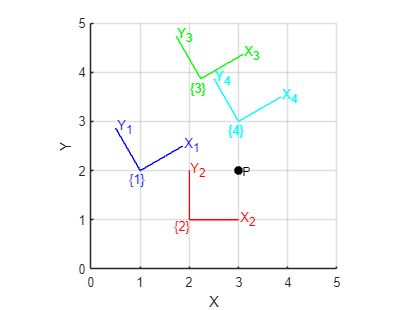


trplot2(T3, 'frame', '3', 'color', 'g');

T4 = T2*T1;
trplot2(T4, 'frame', '4', 'color', 'c');

P = [3 ; 2 ];

plot_point(P, 'label', 'P', 'solid', 'ko');

P1 = inv(T1) * [P; 1]

P1 =     1.7321
   -1.0000
    1.0000



h2e( inv(T1) * e2h(P) )

ans =     1.7321
   -1.0000


## 2.1.2.2 2D centres of rotation

clf
plotvol([-5 4 -1 4.5]);
T0 = eye(3,3);
trplot2(T0, 'frame', '0');
X = transl2(2, 3);
trplot2(X, 'frame', 'X');

R = trot2(2);

trplot2(R*X, 'framelabel', 'RX', 'color', 'r');
trplot2(X*R, 'framelabel', 'XR', 'color', 'r');

C = [1 2]';
plot_point(C, 'label', ' C', 'textcolor', 'k', 'solid', 'ko')

CC = transl2(C)

CC =      1     0     1
     0     1     2
     0     0     1


trplot2(CC, 'framelabel', 'C', 'color', 'g');
trplot2(inv(CC) * X, 'framelabel', 'C1', 'color', 'g');

RC =transl2(C)* R*transl2(-C)

RC =    -0.4161   -0.9093    3.2347
    0.9093   -0.4161    1.9230
         0         0    1.0000


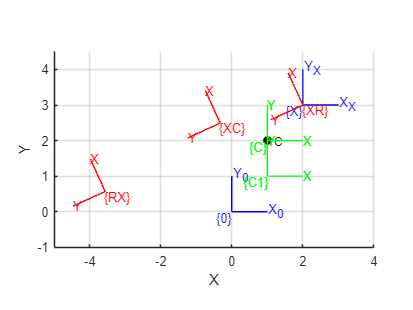

trplot2(RC*X, 'framelabel', 'XC', 'color', 'r');

## 2.1.2.3 2D twists

tw = Twist('R', C)

 
tw = 
( 2  -1; 1 )



tw.T(2)

ans =    -0.4161   -0.9093    3.2347
    0.9093   -0.4161    1.9230
         0         0    1.0000



tw.pole'

ans =      1     2



tw = Twist('T', [1 1])

 
tw = 
( 0.70711  0.70711; 0 )



tw.T(sqrt(2))

ans =      1     0     1
     0     1     1
     0     0     1



T = transl2(2, 3) * trot2(0.5)

T =     0.8776   -0.4794    2.0000
    0.4794    0.8776    3.0000
         0         0    1.0000



tw = Twist(T)

 
tw = 
( 2.7082  2.4372; 0.5 )


tw.T

ans =     0.8776   -0.4794    2.0000
    0.4794    0.8776    3.0000
         0         0    1.0000


## 2.2.1.1 Orthonormal rotation matrix

R = rotx(pi/2)

R =     1.0000         0         0
         0    0.9996   -0.0274
         0    0.0274    0.9996


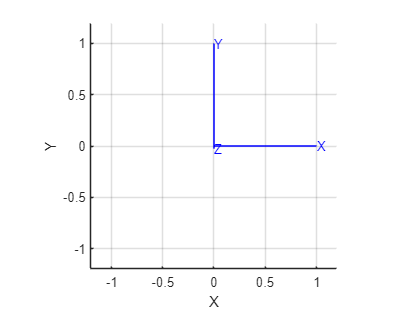


clf
trplot(R)

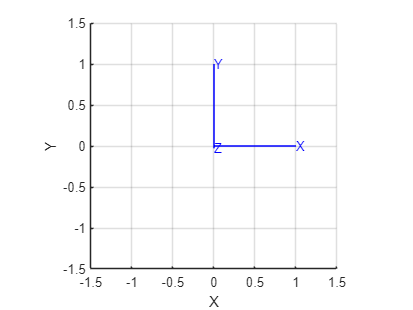


tranimate(R)

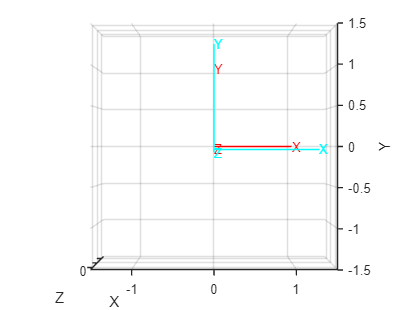


tranimate(R, '3d')


R = rotx(pi/2) * roty(pi/2)

R =     0.9996         0    0.0274
    0.0008    0.9996   -0.0274
   -0.0274    0.0274    0.9992



roty(pi/2)*rotx(pi/2)

ans =     0.9996    0.0008    0.0274
         0    0.9996   -0.0274
   -0.0274    0.0274    0.9992


## 2.2.1.2  3-angle representation

Euler angles

R = rotz(0.1) * roty(0.2) * rotz(0.3);

R = eul2r(0.1, 0.2, 0.3)

R =     1.0000   -0.0070    0.0035
    0.0070    1.0000    0.0000
   -0.0035    0.0000    1.0000



gamma = tr2eul(R)

gamma =     0.0017    0.0035    0.0052



R = eul2r(0.1 , -0.2, 0.3)

R =     1.0000   -0.0070   -0.0035
    0.0070    1.0000   -0.0000
    0.0035   -0.0000    1.0000



tr2eul(R)

ans =    -3.1398    0.0035   -3.1364



eul2r(ans)

ans =     0.9940    0.1093    0.0001
   -0.1093    0.9940   -0.0000
   -0.0001   -0.0000    1.0000



R = eul2r(0.1, 0, 0.3)

R =     1.0000   -0.0070         0
    0.0070    1.0000         0
         0         0    1.0000



tr2eul(R)

ans =          0         0    0.0070


RPY angles

R = rpy2r(0.1, 0.2, 0.3)

R =     1.0000   -0.0052    0.0035
    0.0052    1.0000   -0.0017
   -0.0035    0.0017    1.0000



gamma = tr2rpy(R)

gamma =     0.0017    0.0035    0.0052


reading STL models......
Supermarine Spitfire Mk VIII by Ed Morley @GRABCAD
Gimbal models by Peter Corke using OpenSCAD


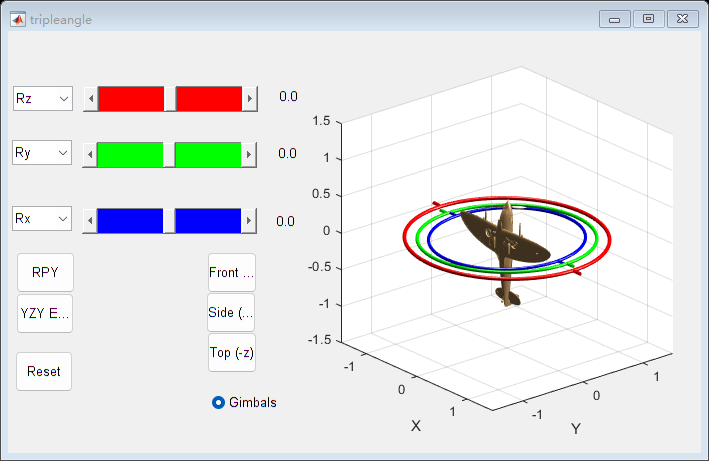


tripleangle

## 2.2.1.4  2-vector representation

a = [1 0 0]';
o = [0 1 0]';
R = oa2r(o, a)

R =      0     0     1
     0     1     0
    -1     0     0


## 2.2.1.5 Rotation about arbitrary vector

R = rpy2r(0.1 , 0.2, 0.3);

[theta, v] = tr2angvec(R)

theta = 0.0065

v =     0.2660    0.5354    0.8016



[x,e] = eig(R)

x =   -0.6816 + 0.0000i  -0.6816 + 0.0000i   0.2660 + 0.0000i
   0.1045 + 0.5880i   0.1045 - 0.5880i   0.5354 + 0.0000i
   0.1564 - 0.3927i   0.1564 + 0.3927i   0.8016 + 0.0000i


e =    1.0000 + 0.0065i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 - 0.0065i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 + 0.0000i



theta = angle(e(1,1))

theta = 0.0065


R = angvec2r(pi/2, [1 0 0])

R =     1.0000         0         0
         0    0.0000   -1.0000
         0    1.0000    0.0000


## 2.2.1.6 matrix exponentials

R = rotx(0.3)

R =     1.0000         0         0
         0    1.0000   -0.0052
         0    0.0052    1.0000



S = logm(R) 

S =          0         0         0
         0   -0.0000   -0.0052
         0    0.0052   -0.0000



vex(S)'

ans =     0.0052         0         0



[th,w] = trlog(R)

th = 0.0052

w =     1.0000
         0
         0



expm(S)

ans =     1.0000         0         0
         0    1.0000   -0.0052
         0    0.0052    1.0000



R = rotx(0.3);

R = expm( skew([1 0 0]) * 0.3 );

## Sidebar: skew symmetric matrices  (page 43)

skew([1 2 3])

ans =      0    -3     2
     3     0    -1
    -2     1     0



vex(ans)'

ans =      1     2     3


## 2.2.1.7 Unit quaternions

q =     ( rpy2tr(0.1, 0.2, 0.3)  )

 
q = 
 
0.99999 < 0.00086809, 0.0017476, 0.0026165 >
 



q = q * q;



inv(q)

 
ans = 
 
0.99998 < -0.0017362, -0.0034952, -0.0052329 >
 



q*inv(q)

 
ans = 
 
1 < 0, 0, 0 >
 



q/q

 
ans = 
 
1 < 0, 0, 0 >
 



q.R

ans =     0.9999   -0.0105    0.0070
    0.0105    0.9999   -0.0034
   -0.0070    0.0035    1.0000


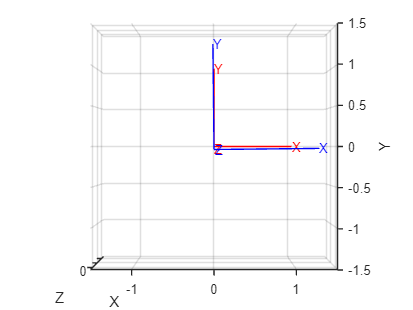


q.plot()


q*[1 0 0]'

ans =     0.9999
    0.0105
   -0.0070


## 2.2.2.1 homogeneous transformation matrix

T = transl(1, 0, 0) * trotx(pi/2) * transl(0, 1, 0)

T =     1.0000         0         0    1.0000
         0    0.9996   -0.0274    0.9996
         0    0.0274    0.9996    0.0274
         0         0         0    1.0000


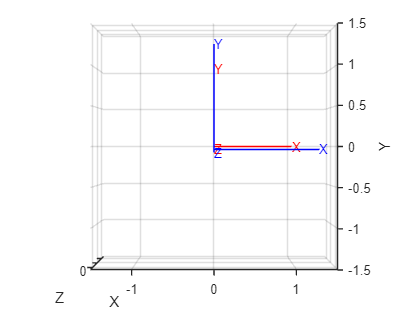


trplot(T)


t2r(T)

ans =     1.0000         0         0
         0    0.9996   -0.0274
         0    0.0274    0.9996



transl(T)'

ans =     1.0000    0.9996    0.0274


## 2.2.2.3 Twists in 3d


$$\mathcal{V}=\left[\begin{array}{c} \omega\\ v\end{array}\right]=\left[\begin{array}{c}\hat{s}\\ -\hat{s}\times q+h\hat{s}\end{array}\right]\dot{\theta} = \mathcal{S}\dot{\theta} \in \mathbb R^6$$


% s(screw), p(point), h(pitch) 
tw = Twist('R', [1 0 0], [0 0 0])  

 
tw = 
( 0  0  0; 1  0  0 )



% \dot{\theta} = 0.3 
% expm(skew([1 0 0]*0.3))
tw.T(0.3)

ans =     1.0000         0         0         0
         0    0.9553   -0.2955         0
         0    0.2955    0.9553         0
         0         0         0    1.0000



% p(point), h=0, s = [0 0 0]'
tw = Twist('T', [0 1 0])

 
tw = 
( 0  1  0; 0  0  0 )



tw.T(2)

ans =      1     0     0     0
     0     1     0     2
     0     0     1     0
     0     0     0     1



X = transl(3, 4, -4);

angles = [0:0.3:15];

% s(screw), p(point), h(pitch) 
tw = Twist('R', [0 0 1], [2 3 2], 0.5);

clf
% 符号用于创建匿名函数
tranimate( @(theta) tw.T(theta) * X, angles, ...
     'length', 0.5, 'retain', 'rgb', 'notext');

% Plücker的  V = -tw.v - tw.pitch * tw.w;
L = tw.line

 
L = 
{ -3  2  -1; 0  0  1 }


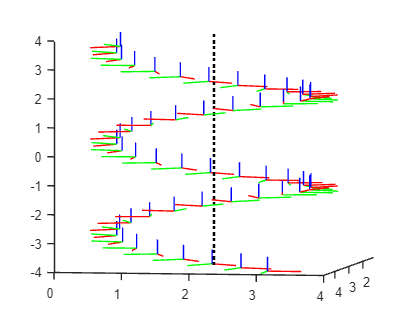

 
L.plot('k:', 'LineWidth', 2)

 
T = transl(1, 2, 3) * eul2tr(0.3, 0.4, 0.5);
tw = Twist(T)

 
tw = 
( 1.0035  1.993  3.0035; 1.2185e-05  0.0069814  0.013963 )



tw.pitch

ans = 0.0559


tw.theta

ans = 0.0156


tw.pole'

ans = 1×3
   -0.4394    0.8952   -0.4472


## 2.3.1 Normalization

R = eye(3,3);
det(R) - 1

ans = 0


% 行列式不再等于1  需要对矩阵进行正则化
for i=1:100
       R = R * rpy2r(0.2, 0.3, 0.4);
end
det(R) - 1

ans = -1.4544e-14



R = trnorm(R);
det(R) - 1

ans = 2.2204e-16


% 单位四元数的范数或幅度不再等于1
q = q.unit();

q2 = q;  % ADDITION

% 乘法之后显式归一化
q = q .* q2;

## more twists

tw = Twist('R', [1 0 0], [0 0 0])

 
tw = 
( 0  0  0; 1  0  0 )



% S 是旋量   v w 是对应分量
tw.S'

ans =      0     0     0     1     0     0


tw.v'

ans =      0     0     0


tw.w'

ans =      1     0     0



% se 是 S 旋量的李代数  
tw.se 

ans =      0     0     0     0
     0     0    -1     0
     0     1     0     0
     0     0     0     0



% T 是 S 旋量的李群  == trexp(tw.se)
tw.T(0.3)

ans =     1.0000         0         0         0
         0    0.9553   -0.2955         0
         0    0.2955    0.9553         0
         0         0         0    1.0000



tw.line

 
ans = 
{ -0  -0  -0; 1  0  0 }



t2 = tw * tw

 
t2 = 
( 0  0  0; 2  0  0 )


tr2angvec(t2.T)

Rotation: 2.000000 rad x [1.000000 0.000000 0.000000]


## 2.4 Using the toolbox

%X, Y, THETA 
T1 = SE2(1, 2, 30, 'deg')

 

T1 = 
    0.8660   -0.5000         1
    0.5000    0.8660         2
         0         0         1


about T1

T1 [SE2] : 1x1 (72 bytes)


SE3

 

ans = 
         1         0         0         0
         0         1         0         0
         0         0         1         0
         0         0         0         1


T1 

 

T1 = 
    0.8660   -0.5000         1
    0.5000    0.8660         2
         0         0         1



% T1 是类   T1.T才是矩阵数据
T1.T    

ans =     0.8660   -0.5000    1.0000
    0.5000    0.8660    2.0000
         0         0    1.0000


about ans

ans [double] : 3x3 (72 bytes)



inv(T1) * P

ans =     1.7321
   -1.0000


### 验证 四元数的计算

point = [1,2,3]'

point =      1
     2
     3


s1 = SO3(rpy2r(pi/2,0,0));
s2 = SO3(rpy2r(0,0,pi/2));
q1 =  s1.UnitQuaternion

 
q1 = 
 
0.99991 < 0.013707, 0, 0 >
 


q2 =  s2.UnitQuaternion

 
q2 = 
 
0.99991 < 0, 0, 0.013707 >
 


矩阵复合

% so 
s= s1 * s2

 

s = 
    0.9996   -0.0274         0
    0.0274    0.9992   -0.0274
    0.0008    0.0274    0.9996



% 四元数
q = q1 .* q2

 
q = 
 
0.99981 < 0.013706, -0.00018789, 0.013706 >
 


q.R

ans =     0.9996   -0.0274    0.0000
    0.0274    0.9992   -0.0274
    0.0008    0.0274    0.9996



% 内部实现
q2vec = [q2.s q2.v]';
qvec = (q1.matrix * q2vec)'

qvec =     0.9998    0.0137   -0.0002    0.0137


UnitQuaternion(qvec).R

ans =     0.9996   -0.0274    0.0000
    0.0274    0.9992   -0.0274
    0.0008    0.0274    0.9996


求逆

% so 
sinv = s.inv()

 

sinv = 
    0.9996    0.0274    0.0008
   -0.0274    0.9992    0.0274
         0   -0.0274    0.9996



% 四元数
q.inv

 
ans = 
 
0.99981 < -0.013706, 0.00018789, -0.013706 >
 


q.inv.R

ans =     0.9996    0.0274    0.0008
   -0.0274    0.9992    0.0274
    0.0000   -0.0274    0.9996



% 内部实现
[qvec(1) -qvec(2:4)]

ans =     0.9998   -0.0137    0.0002   -0.0137


旋转向量 

% so
point_1 = s * point

point_1 =     0.9448
    1.9437
    3.0544



% 四元数
q * point

ans =     0.9448
    1.9437
    3.0544



% 内部实现
pure = UnitQuaternion.pure(point)

 
pure = 
 
0 << 1, 2, 3 >>
 


q * pure * q.inv

 
ans = 
 
0 << 0.9448, 1.9437, 3.0544 >>
 


**微分**

% so3
[theta,V]  = s.toangvec;
dot_s = s * skew(V) 

dot_s =    -0.0194   -0.7068    0.0097
    0.7063   -0.0388   -0.7068
    0.0291    0.7063   -0.0194


 


% 单位四元数的导数不是一个单位四元数    不能是 q.unit.R
q.dot(V)

 
ans = 
 
-0.0096921 << 0.35347, -0.0048456, 0.35347 >>
 



[theta,V_inv] = s.inv.toangvec;
q.dotb(V_inv)

 
ans = 
 
0.0096921 << -0.35347, 0.0048456, -0.35347 >>
 


### 验证  平移 + 四元数  的计算 

t1 = [1,2,3]';
t2 = [0 0 3]';
s1 = SE3(rpy2r(pi/2,0,0),t1)

 

s1 = 
         1         0         0         1
         0    0.9996   -0.0274         2
         0    0.0274    0.9996         3
         0         0         0         1


s2 = SE3(rpy2r(0,0,pi/2),t2)

 

s2 = 
    0.9996   -0.0274         0         0
    0.0274    0.9996         0         0
         0         0         1         3
         0         0         0         1



q1 =  s1.UnitQuaternion

 
q1 = 
 
0.99991 < 0.013707, 0, 0 >
 


q2 =  s2.UnitQuaternion

 
q2 = 
 
0.99991 < 0, 0, 0.013707 >
 


矩阵复合

% so 
s= s1 * s2

 

s = 
    0.9996   -0.0274         0         1
    0.0274    0.9992   -0.0274     1.918
    0.0008    0.0274    0.9996     5.999
         0         0         0         1



% 四元数
q = q1 .* q2;
q.R

ans =     0.9996   -0.0274    0.0000
    0.0274    0.9992   -0.0274
    0.0008    0.0274    0.9996


t = t1 + q1 * t2

t =     1.0000
    1.9178
    5.9989


求逆

% so 
sinv = s.inv()

 

sinv = 
    0.9996    0.0274    0.0008    -1.057
   -0.0274    0.9992    0.0274    -2.053
         0   -0.0274    0.9996    -5.944
         0         0         0         1



% 四元数
q.inv.R

ans =     0.9996    0.0274    0.0008
   -0.0274    0.9992    0.0274
    0.0000   -0.0274    0.9996


-(q.inv * t)

ans =    -1.0567
   -2.0533
   -5.9440


旋转向量 

% so
s * point

ans =     1.9448
    3.8614
    9.0533



% 四元数
q * point +t

ans =     1.9448
    3.8614
    9.0533
